# Test for correctness of the measurement update formula

# Simulation For Multi-agent Pose Estimation Based on Distributed Iterative Invariant Kalman Filter (DIInKF)

*In this scripts, we only take the 5 agents case as an example. But we have tried our best to make scripts easy to extend to other scenes like more agents. You can feel free to use this, but please refer to our work.*

When run this code at the first time, you need to run **gen_data** first to get the simulated dataset.  

We will compare the following methods:

- (Control Group):Independent IMU propagation with part of the agent update while seeing the feature. 

- (Control Group):  C-InEKF: centralized InEKF

- D-EKF: distributed EKF with fast covariance intersection ~(CI)

- D-InEKF-fastCI: distributed EKF with fast CI

- D-InEKF-SeCI: distributed EKF with sequential CI

- D-IEKF-fastCI: distributed iterative EKF with fast CI

- D-IInEKF-fastCI:  distributed iterative InEKF with fast CI

Evaluation quantities including:

- Average time per step

- Absolute trajectory error~(ATE) curve and average ATE rmse for each agent's trajectoroies

- Average ATE rmse of all agents

clc;clear;
addpath(genpath(pwd));
load("dataset\data_s1.mat");

## Initial Settings

### Initialization


N_imu=1;
N_mea=2;
t_update_set=[];
N_update_set=[];
N_ROBOTS=1;
method=[1,0];

### Set the initial bias

State structure:

remark: we track pimu, Rimu, vimu, ba, bg.

% IMU state initial error for 5 agents (We assume that they have the same bias for simplicity coding)
bia_R_imu_angle=[0,0,0];
bia_R_imu = angle2dcm(bia_R_imu_angle(1), bia_R_imu_angle(2), bia_R_imu_angle(3));
bia_p_imu =[0,0,0];
bia_v_imu = [0,0,0];% zeros(1,3);
bia_b_a   = [0,0,0];
bia_b_g   = [0.00,0.00,0.00];

initializer=[]; %structure to save the initial (X,P)

X_init.Rimu=bia_R_imu*T_real0(1:3, 1:3);
X_init.pimu=T_real0(1:3, 4)'+bia_p_imu;
X_init.vimu=IMU_data(N_imu).v_inglobal_real+bia_v_imu;
X_init.ba=b_a_real + bia_b_a;
X_init.bg=b_g_real + bia_b_g;


P_init= 10e-2*eye(9);

#### Set noises

SIGMA_SET.sigma_a=sigma_a;
SIGMA_SET.sigma_g=sigma_g;
SIGMA_SET.sigma_bg=sigma_bg;
SIGMA_SET.sigma_ba=sigma_ba;
SIGMA_SET.sigma_cam=sigma_cam;


解耦运行

IF_VI_UPDATE=0;
IF_CI = 0;
IF_CONSENSUS =0;
IF_OBJUPDATE=1;
traceP=[];
np=1;

## Estimate NowControl Group: Independently propagation.

--------------/RMSE/-------------
Robots 


i = 1

Orientation(rad): 
Err_IMU_R | 0.10083
Position(m):
Err_IMU_p | 1.9883


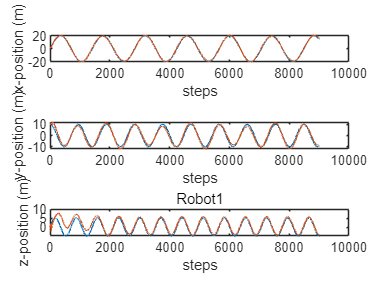

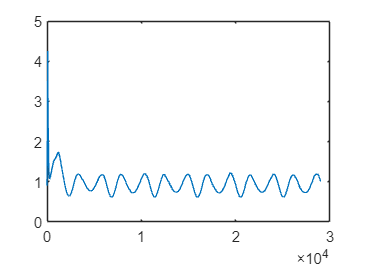

if(method(1))
N_imu=1;
N_update=1;
t_update_set(N_update)=0;
N_update_set(N_update)=1;

N_mea=2;%here we generate update time set to make it easy for evluation  
N_cam=2;
CAM_IF_UPDATE=0;% Value 1 means that new camera measurement is received.

IMU_data=IMU_data;
t_imu=IMU_data(N_imu).t;

method1(1).X(N_update)=X_init;
X_last=X_init;
P_last=P_init;%最初是只有9*9的信息。


X_robots.objectlist=[];
X_robots.Tobj=[];
X_robots.objinorder=[];
X_robots.X_last(N_imu).X=X_last;
X_robots.X_last(N_imu).X_aug=[];
init=1;

while(t_imu<T_WORKING)

%% Propagate
    t_imu=IMU_data(N_imu).t;
    acc_m=IMU_data(N_imu).a;
    w_m=IMU_data(N_imu).w;
    [X_pred, P_pred]=  inEKF_propagate(X_last, P_last, w_m, acc_m, dti, SIGMA_SET);
    X_last = X_pred; P_last = P_pred;
    X_robots.X_last(N_imu+1).X=X_pred;
    traceP(np)=trace(P_pred(1:9,1:9));
    np=np+1;
% %% Object Update
    if(IF_OBJUPDATE)
        t_mea=m_data(N_mea).t;
        if(abs(t_imu-t_mea)<0.000000001)
            Xo_update=X_last;
            Po_update=P_last;
            X_object_update=X_robots.Tobj;
            num_see_feature=m_data(N_mea).robot(1).feature_flag; %number of the effective features.
            if(num_see_feature) 
                T_mea_feature=m_data(N_mea).robot(1).m_feature; 
                % 初始化之前没有看过的状态
                if(init)
                    P_augment = zeros(9+num_see_feature*6, 9+num_see_feature*6);
                    P_augment(1:9,1:9)=P_last;
                    J=zeros(6,9);   J(1:6,1:6)=eye(6);
                    R_if = sigma_if(1)*sigma_if(1)*eye(6);
                    for mm = 1:num_see_feature
                        P_augment(9+(mm-1)*6+1:9+mm*6, 9+(mm-1)*6+1:9+mm*6) = P_last(1:6,1:6)+R_if;
              
                        P_f_old=P_augment(1:9+(mm-1)*6,1:9+(mm-1)*6);
                        dimen=length(P_f_old);
                        J_d=zeros(6, dimen);
                        J_d(1:6,1:6)=eye(6);
                        P_if =P_f_old*J_d';
                        P_augment(1:dimen, dimen+1:dimen+6)=P_if; % 9*9*9*6
                        P_augment(dimen+1:dimen+6, 1:dimen)= P_if';
                          
                        T_i = eye(4);
                        T_i(1:3,1:3)=X_last.Rimu;
                        T_i(1:3,4) = X_last.pimu';
                        X_robots.Tobj(mm).T = T_i * T_mea_feature(mm).T;
                        Po_update=P_augment;
                    end
                    init=0;
                    traceP(np)=trace(Po_update(1:9,1:9));
                    np=np+1;

                end
                if(~init)
                    
                    [Xo_update,Po_update,X_object_update]=inEKF_obj_one_update(X_pred, Po_update, X_robots.Tobj, T_mea_feature, sigma_if(1), num_see_feature);     
                    Po_update=(Po_update+Po_update')/2;
                    traceP(np)=trace(Po_update(1:9,1:9));
                    np=np+1;
                end
            end

            X_robots.Tobj=X_object_update;
            X_robots.X_last(N_imu+1).X=Xo_update;
          
            N_update=N_update+1;
            method1(1).X(N_update)=Xo_update;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;
            N_update_set(N_update)=N_imu;
            
            P_last = Po_update; 
            X_last = Xo_update;
        end
    end

%% Consensus
    if(IF_CONSENSUS)


    end


%% VI update
   
        t_cam=cam_data(N_cam).timestamp;
        if ((abs(t_cam-t_imu)<0.0000001))
            CAM_IF_UPDATE=1;
            camera_measure_now=cam_data(N_cam);
            number_of_features_seen = length(camera_measure_now.uv); 
            itermax=1;
            X_objup= X_robots.Tobj;
            Xv_update=X_last;
            P_esti=P_last;
            if(number_of_features_seen)
                if(IF_VI_UPDATE)
                    [Xv_update, P_esti, X_objup]=inEKF_iter_update(X_pred, P_pred, CAM_IF_UPDATE,acc_m,w_m,camera_measure_now, SIGMA_SET, itermax,CAM_INTRISIC, p_camera_in_IMU_real, R_camera_in_IMU_real, X_robots.Tobj);
                end
            end
            X_robots.Tobj=X_objup;
            X_robots.X_last(N_imu+1).X=Xv_update;
            P_robots.P_last(N_imu+1).P=P_esti;
            traceP(np)=trace(P_esti(1:9,1:9));
            np=np+1;
            N_update=N_update+1;
            method1(1).X(N_update)=Xv_update;
            t_update_set(N_update)=t_cam;
            N_update_set(N_update)=N_imu;
            P_last = P_esti; 
            X_last = Xv_update;
           
       
        if(CAM_IF_UPDATE==1)%是否进行更新是由时间决定的。
            N_cam=N_cam+1;
            CAM_IF_UPDATE=0;
        end
    end

%% CI 
    if(IF_CI)


    end



    N_imu=N_imu+1;
end



% The real path all will be used in evaluation.
real_path_all=[];


real_path_select = filterArrayByIndex(real_path,N_update_set);
real_path_all(1).rp=real_path_select;


ATE_single(real_path_all, method1);
figure();
plot(1:length(traceP), traceP(1:end));
aver=mean(traceP(1:end));
end

method 2 MSCKF

Stack_mea=[];
N_MAX=10;
if(method(2))
N_imu=1;
N_update=1;
t_update_set(N_update)=0;
N_update_set(N_update)=1;

N_mea=2;%here we generate update time set to make it easy for evluation  
N_cam=2;
CAM_IF_UPDATE=0;% Value 1 means that new camera measurement is received.

IMU_data=IMU_data;
t_imu=IMU_data(N_imu).t;

method1(1).X(N_update)=X_init;
X_last=X_init;
P_last=P_init;%最初是只有9*9的信息。


X_robots.objectlist=[];
X_robots.Tobj=[];
X_robots.objinorder=[];
X_robots.X_last(N_imu).X=X_last;

init=1;

while(t_imu<T_WORKING)

%% Propagate
    t_imu=IMU_data(N_imu).t;
    acc_m=IMU_data(N_imu).a;
    w_m=IMU_data(N_imu).w;
    [X_pred, P_pred]=  inEKF_propagate(X_last, P_last, w_m, acc_m, dti, SIGMA_SET);
    X_last = X_pred; P_last = P_pred;
    X_robots.X_last(N_imu+1)=X_robots.X_last(N_imu);
    X_robots.X_last(N_imu+1).X=X_pred;
    X_robots.X_last(N_imu+1).Xaug(1).X=X_pred;
    traceP(np)=trace(P_pred(1:9,1:9));
    np=np+1;
% %% Object Update
    if(IF_OBJUPDATE)
        t_mea=m_data(N_mea).t;
        if(abs(t_imu-t_mea)<0.000000001)
            Xo_update=X_last;
            Po_update=P_last;
            X_object_update=X_robots.Tobj;
            num_see_feature=m_data(N_mea).robot(1).feature_flag; %number of the effective features.
            if(num_see_feature) %当看到object feature时候
                T_mea_feature=m_data(N_mea).robot(1).m_feature; %取出这一时刻的测量
                % 记录下来此刻的状态
                N_record=length(Stack_mea);
                if(N_record<N_MAX)
                    X_i=X_robots.X_last(N_imu+1).X;
                    X_robots.X_last(N_imu+1).Xaug(end+1).X=X_i;
                    P_aug=Covariance_aug_one(Po_update);
                    Po_update=P_aug;
                    Stack_mea(end+1).m=T_mea_feature;
                end
          
                if(N_record>=N_MAX)
                     %刚开始在积累这个滑动窗口里面的测量，当达到窗口大小时候，之后每次扔掉第N_max/3的老的帧
                     Stack_tmp=Stack_mea;

                     N_throw=floor(N_MAX/3);
                   
                     Stack_tmp(N_throw:N_MAX-1)=Stack_mea(N_throw+1:end);
                     Stack_tmp(end).m=T_mea_feature;
                    
                     %Group state stack
                     X_auglist=X_robots.X_last(N_imu+1).Xaug;
                     X_auglist_tmp=X_auglist;
                     X_auglist_tmp(1:N_throw-1)=X_auglist(1:N_throw-1);
                     X_auglist_tmp(N_throw:N_MAX-1)=X_auglist(N_throw+1:end-1);
                     X_auglist_tmp(N_MAX).X=X_robots.X_last(N_imu+1).X;
                     X_robots.X_last(N_imu+1).Xaug=X_auglist_tmp;
                     %协方差先扔掉再增加
                     %%扔掉N_throw
                     P_aug_tmp=zeros(9+N_MAX*6-6, 9+N_MAX*6-6);
                     P_aug_tmp(1:9+6*(N_throw-1),1:9+6*(N_throw-1))=P_aug(1:9+6*(N_throw-1),1:9+6*(N_throw-1));
                     P_aug_tmp(9+6*N_throw-5:9+6*(N_MAX-1),9+6*N_throw-5:9+6*(N_MAX-1))= P_aug(9+N_throw*6+1: end,  9+N_throw*6+1:end);
                     P_xy=P_aug(1:9+6*N_throw, 9+6*N_throw+1:end);

                     P_aug_tmp(1:9+6*N_throw, 9+6*N_throw-5:end )=P_xy;
                     P_aug_tmp(9+6*N_throw-5:end,1:9+6*N_throw)=P_xy';

                     % 增加
                     P_new= Covariance_aug_one(P_aug_tmp);
                     Po_update=P_new;
                     [X_update, P_update, X_object_update]=Invariant_MSCKF_object_update(X_pred, P_pred, X_object, obj_order, Stack_mea, sigma_if, num_see_feature);
                     
                end
             
            end

            X_robots.Tobj=X_object_update;
            
            X_robots.X_last(N_imu+1).X=Xo_update;
           
            N_update=N_update+1;
            method1(1).X(N_update)=Xo_update;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;
            N_update_set(N_update)=N_imu;
            
            P_last = Po_update; 
            X_last = Xo_update;
        end
    end

%% Consensus
    if(IF_CONSENSUS)


    end


%% VI update
   
        t_cam=cam_data(N_cam).timestamp;
        if ((abs(t_cam-t_imu)<0.0000001))
            CAM_IF_UPDATE=1;
            camera_measure_now=cam_data(N_cam);
            number_of_features_seen = length(camera_measure_now.uv); 
            itermax=1;
            X_objup= X_robots.Tobj;
            Xv_update=X_last;
            P_esti=P_last;
            if(number_of_features_seen)
                if(IF_VI_UPDATE)
                    [Xv_update, P_esti, X_objup]=inEKF_iter_update(X_pred, P_pred, CAM_IF_UPDATE,acc_m,w_m,camera_measure_now, SIGMA_SET, itermax,CAM_INTRISIC, p_camera_in_IMU_real, R_camera_in_IMU_real, X_robots.Tobj);
                end
            end
            X_robots.Tobj=X_objup;
            X_robots.X_last(N_imu+1).X=Xv_update;
            P_robots.P_last(N_imu+1).P=P_esti;
            traceP(np)=trace(P_esti(1:9,1:9));
            np=np+1;
            N_update=N_update+1;
            method1(1).X(N_update)=Xv_update;
            t_update_set(N_update)=t_cam;
            N_update_set(N_update)=N_imu;
            P_last = P_esti; 
            X_last = Xv_update;
           
       
        if(CAM_IF_UPDATE==1)%是否进行更新是由时间决定的。
            N_cam=N_cam+1;
            CAM_IF_UPDATE=0;
        end
    end

%% CI 
    if(IF_CI)


    end


   
    N_imu=N_imu+1;
end



% The real path all will be used in evaluation.
real_path_all=[];


real_path_select = filterArrayByIndex(real_path,N_update_set);
real_path_all(1).rp=real_path_select;


ATE_single(real_path_all, method1);
figure();
plot(1:length(traceP), traceP(1:end));
aver=mean(traceP(1:end));
end